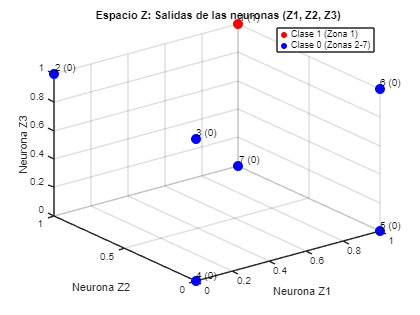

%% Solución corregida (solo Zona 1 = clase 1, resto = clase 0)
clc; clear; close all;

%% Datos proporcionados (salidas de las neuronas por zona)
zonas = [
    1, 1, 1, 1;  % Zona 1 (Z1, Z2, Z3) -> Clase 1
    2, 0, 1, 1;   % Zona 2 -> Clase 0
    3, 0, 0, 1;    % Zona 3 -> Clase 0
    4, 0, 0, 0;    % Zona 4 -> Clase 0
    5, 1, 0, 0;    % Zona 5 -> Clase 0
    6, 1, 0, 1;    % Zona 6 -> Clase 0
    7, 1, 1, 0     % Zona 7 -> Clase 0
];

% Clases deseadas (solo Zona 1 = 1, resto = 0)
clases = [1; 0; 0; 0; 0; 0; 0];

%% Apartado 3: Graficar en el espacio Z
figure;
hold on;
grid on;
view(3);
title('Espacio Z: Salidas de las neuronas (Z1, Z2, Z3)');
xlabel('Neurona Z1');
ylabel('Neurona Z2');
zlabel('Neurona Z3');
axis([0 1 0 1 0 1]);

% Graficar puntos
scatter3(zonas(1,2), zonas(1,3), zonas(1,4), 100, 'r', 'filled'); % Zona 1 (clase 1)
scatter3(zonas(2:7,2), zonas(2:7,3), zonas(2:7,4), 100, 'b', 'filled'); % Zonas 2-7 (clase 0)

% Etiquetar cada punto con el número de zona
for i = 1:size(zonas, 1)
    text(zonas(i,2), zonas(i,3), zonas(i,4), sprintf('%d (%d)', zonas(i,1), clases(i)), ...
        'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
end

legend({'Clase 1 (Zona 1)', 'Clase 0 (Zonas 2-7)'}, 'Location', 'best');

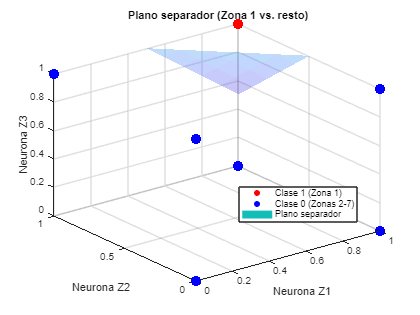


%% Apartado 4: Plano separador (solo Zona 1 vs. resto)
% El plano debe dejar la Zona 1 (1,1,1) en un lado y el resto en el otro.
% Una solución trivial es el plano: Z1 + Z2 + Z3 - 2.5 = 0

% Definir el plano manualmente (ajustado para separar solo la Zona 1)
w0 = -2.5; w1 = 1; w2 = 1; w3 = 1;  % Ecuación: 1*Z1 + 1*Z2 + 1*Z3 - 2.5 = 0

% Graficar el plano
[Z1g, Z2g] = meshgrid(0:0.1:1, 0:0.1:1);
Z3g = (-w0 - w1*Z1g - w2*Z2g) / w3;

figure;
hold on;
grid on;
view(3);
title('Plano separador (Zona 1 vs. resto)');
xlabel('Neurona Z1');
ylabel('Neurona Z2');
zlabel('Neurona Z3');
axis([0 1 0 1 0 1]);

% Puntos
scatter3(zonas(1,2), zonas(1,3), zonas(1,4), 100, 'r', 'filled');
scatter3(zonas(2:7,2), zonas(2:7,3), zonas(2:7,4), 100, 'b', 'filled');

% Plano
surf(Z1g, Z2g, Z3g, 'FaceAlpha', 0.3, 'EdgeColor', 'none');
legend({'Clase 1 (Zona 1)', 'Clase 0 (Zonas 2-7)', 'Plano separador'}, 'Location', 'best');


%% Verificación
fprintf('Ecuación del plano separador:\n%.2f + %.2f*Z1 + %.2f*Z2 + %.2f*Z3 = 0\n', w0, w1, w2, w3);

Ecuación del plano separador:
-2.50 + 1.00*Z1 + 1.00*Z2 + 1.00*Z3 = 0


fprintf('\nVerificación:\n');


Verificación:


for i = 1:size(zonas, 1)
    z = zonas(i, 2:4);
    pred = (w0 + w1*z(1) + w2*z(2) + w3*z(3)) > 0;
    fprintf('Zona %d: Clase real = %d, Clase predicha = %d\n', zonas(i,1), clases(i), pred);
end

Zona 1: Clase real = 1, Clase predicha = 1
Zona 2: Clase real = 0, Clase predicha = 0
Zona 3: Clase real = 0, Clase predicha = 0
Zona 4: Clase real = 0, Clase predicha = 0
Zona 5: Clase real = 0, Clase predicha = 0
Zona 6: Clase real = 0, Clase predicha = 0
Zona 7: Clase real = 0, Clase predicha = 0
